run("master_setting_sheet.mlx");

% vector format : [longitudanal lateral vertical]
patch_force_max_accel = [1500 1800 0]; %[N] wheel forces during max acceleration
patch_force_max_cornerBrake = [700 1800 1800]; %[N] wheel forces furing max cornering+brake

bC = gearbox.bearingCenterDistance; % distance between centers of inboard and outboard bearings
fD = gearbox.faceCenterDistance; % distance between center of inboard bearing and wheel face-hub interface

r_max_accel = getReaction(patch_force_max_accel,bC,fD); %[N] bearing reaction forces for max accel case
r_max_cornerBrake = getReaction(patch_force_max_cornerBrake,bC,fD); %[N] bearing reaction forces for max corner+brake case
r_effective =max([r_max_accel r_max_cornerBrake]);%0.6*r_max_accel+0.4*r_max_cornerBrake;

%calculation factors from bearing webpage
f = wheelbearing.f; % size factor
f1 = wheelbearing.f1; % contact angle factor
f2 = wheelbearing.f2; % preload class factor
g = wheelbearing.g; % internal preload

preload = f*f1*f2*g;  % preload calculation from page 162 of skf super precision angular contact bearing catalog
equivalent_axial_load = preload+0.67 * r_effective(3); % see page 190 of the skf super precision angular contact bearing catalog
f0 = wheelbearing.f0; % calculation factor from bearing page on skf website
C0 = wheelbearing.C0; % static load rating [N]
C = wheelbearing.C; % dynamic load rating [N]

%calculation factors
cf = getFactors(f0,equivalent_axial_load,C0); %function to retrieve values from Table 38 on page 191 of super precision catalog

P = getEqDynamicLoad(r_effective,cf);
P0 = getEqStaticLoad(r_effective,cf);
s0 = wheelbearing.s0; %static safety factor (pg 36)
l10 = (10^6)*(C/P)^3;   % no of revolutions pg 34
dist = l10*wheel.radius/1000;   % convert revolution to distance using wheel radius
max_axial_force = preload*2.83; % (only for back to back angular contact) maximum axial force before the preload on the unloaded bearing goes to zero and wear increase dramatically
fs = wheelbearing.fs;  % minimum axial clamping force
fc = wheelbearing.fc; % minimum fitting force
Pa = fs+fc+g; % required axial force
k = wheelbearing.k; % torque conversion factor for m6 thread 
nb = gearbox.shoulderBolts.num; % number of bolts
m=k*Pa/nb; % required torque

fprintf("Preload: %.1f [N]",preload);

Preload: 612.1 [N]

fprintf("Equivalent Static Load: %.1f [N]",P0);

Equivalent Static Load: 1656.0 [N]

fprintf("Equivalent Dynamic Load: %.1f [N]",P);

Equivalent Dynamic Load: 3276.0 [N]

fprintf("Distance until failure: %.1f [km]",dist);

Distance until failure: 77877.1 [km]

fprintf("Maximum allowable cornering force %.1f [N]",max_axial_force);

Maximum allowable cornering force 1732.4 [N]

fprintf("Tightening torque for %d bolts: %.1f [Nm]",nb,m/100);

Tightening torque for 3 bolts: 39.4 [Nm]


$$\begin{array}{l}
F_w +B_i +B_o =0\;\;\left\lbrack \mathrm{Force}\;\mathrm{balance}\;\mathrm{in}\;X\;\mathrm{or}\;Y\;\mathrm{direction}\right\rbrack \\
\left(F_d -B_c \right)\times B_o +F_d \times B_i =0\;\;\left\lbrack \mathrm{Moment}\;\mathrm{balance}\;\mathrm{around}\;\mathrm{face}\right\rbrack \\
{\to \;B}_o =B_{i\;} \times \frac{F_{d\;} }{\;F_d -B_c }\\
\to F_w +B_{i\;} +B_i \left(\frac{F_{d\;} }{F_{d\;} -B_c }\right)=0\\
\to F_w +B_{i\;} \left(1+\frac{F_{d\;} }{F_{d\;} -B_c }\right)=0\\
\to F_{w\;} +B_i \left(\frac{2F_d -B_c }{F_d -B_c }\right)=0\\
\to B_i =-F_{w\;} \left(\frac{F_d -B_c }{2F_d -B_c }\right)\\
B_{o\;,Z} =\left\lbrace \begin{array}{ll}
F_{w,Z} , & F_{w,Z} <0\\
0, & F_{w,Z} \ge 
\end{array}\right.\\
B_{i\;,Z} =\left\lbrace \begin{array}{ll}
0, & F_{w,Z} <0\\
F_{w,Z} , & F_{w,Z} \ge 0
\end{array}\right.
\end{array}$$


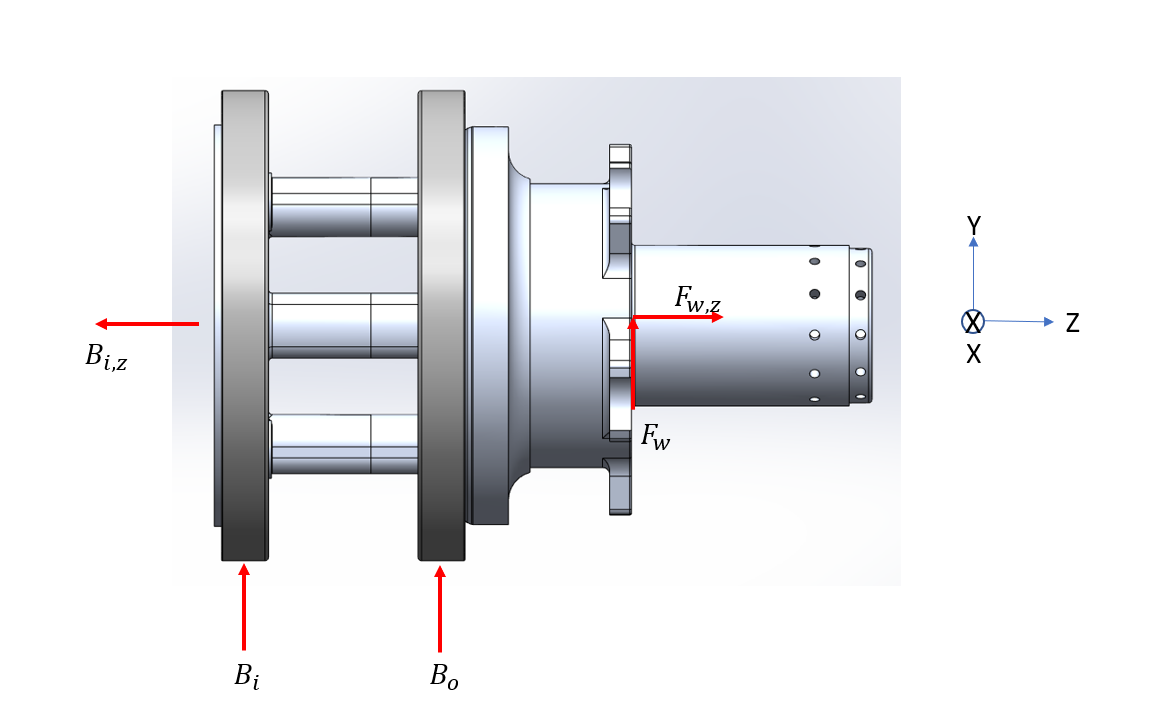

function B = getReaction(Fw,bD,fC) %impelements force and moment balance equations shown above
    bi = zeros(3,1);

    bi(1:2) = -((fC-bD)/(2*fC-bD)).*Fw(1:2);
    bo = bi.*(fC)/(fC-bD);
    if(Fw(3) > 0)
        bi(3) = Fw(3);
        bo(3) = 0;
    else
        bi(3) = 0;
        bo(3) = Fw(3);
    end
    B = [bi bo];
end


function cf = getFactors(f0,fA,C0) %function to return values from table 38 on pg 191 of the catalog
    det = 2*f0*fA/C0;
    if det<=0.178
        factors = [0.38 0.72 1.65 2.39 0.92];
    elseif det<=0.357
        factors = [0.4 0.72 1.57 2.28 0.92];
    elseif det<=0.714
        factors = [0.43 0.72 1.46 2.11 0.92];
    elseif det<=1.07
        factors = [0.46 0.72 1.38 2 0.92];
    elseif det<=1.43
        factors = [0.47 0.72 1.34 1.93 0.92];
    elseif det<=2.14
        factors = [0.5 0.72 1.26 1.82 0.92];
    elseif det<=3.57
        factors = [0.55 0.72 1.14 1.66 0.92];
    else
        factors = [0.56 0.72 1.12 1.63 0.92];
    end

    cf.e = factors(1);
    cf.x2 = factors(2);
    cf.y1 = factors(3);
    cf.y2 = factors(4);
    cf.y0 = factors(5);
end

function P = getEqDynamicLoad(f,cf)
    fr = sqrt(f(1)^2+f(2)^2); % radial force
    fa = f(3); %axial force
    if fa/fr <= cf.e % dynamic load calculation from pg 190
        P = fr + cf.y1*fa;
    else
        P = cf.x2*fr+cf.y2*fa;
    end
end

function P0 = getEqStaticLoad(f,cf) 
    fr = sqrt(f(1)^2+f(2)^2); % radial force
    fa = f(3); % axial force
    P0 = fr+cf.y0*fa; % static load calculation from pg 191
end